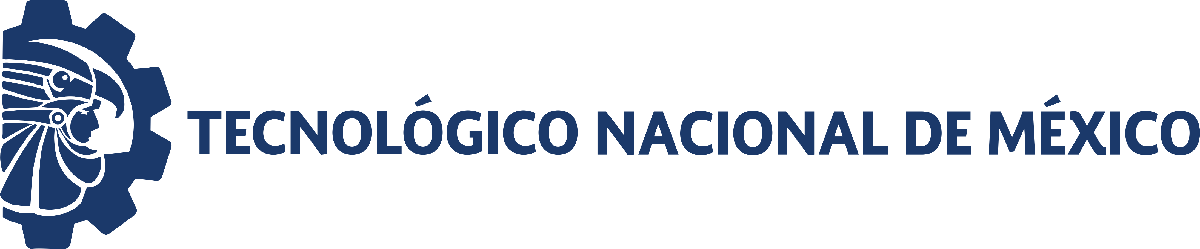                                 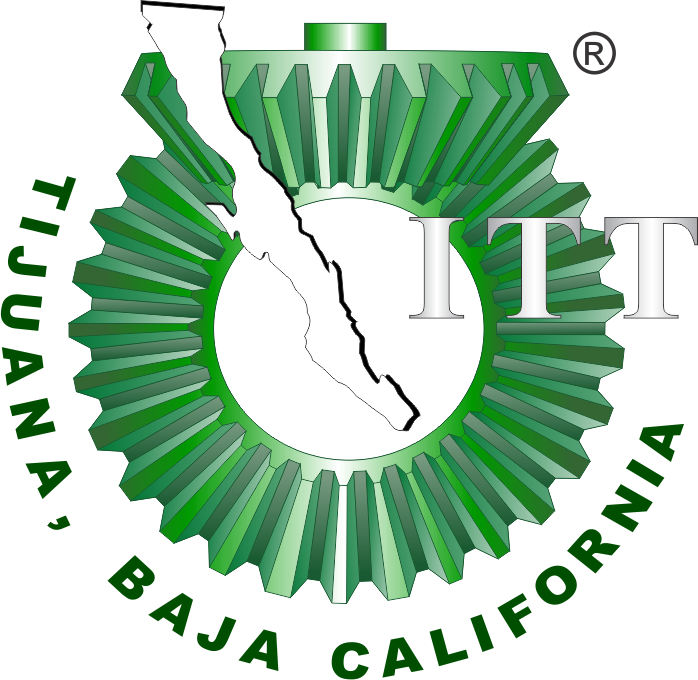

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Final project

## General information

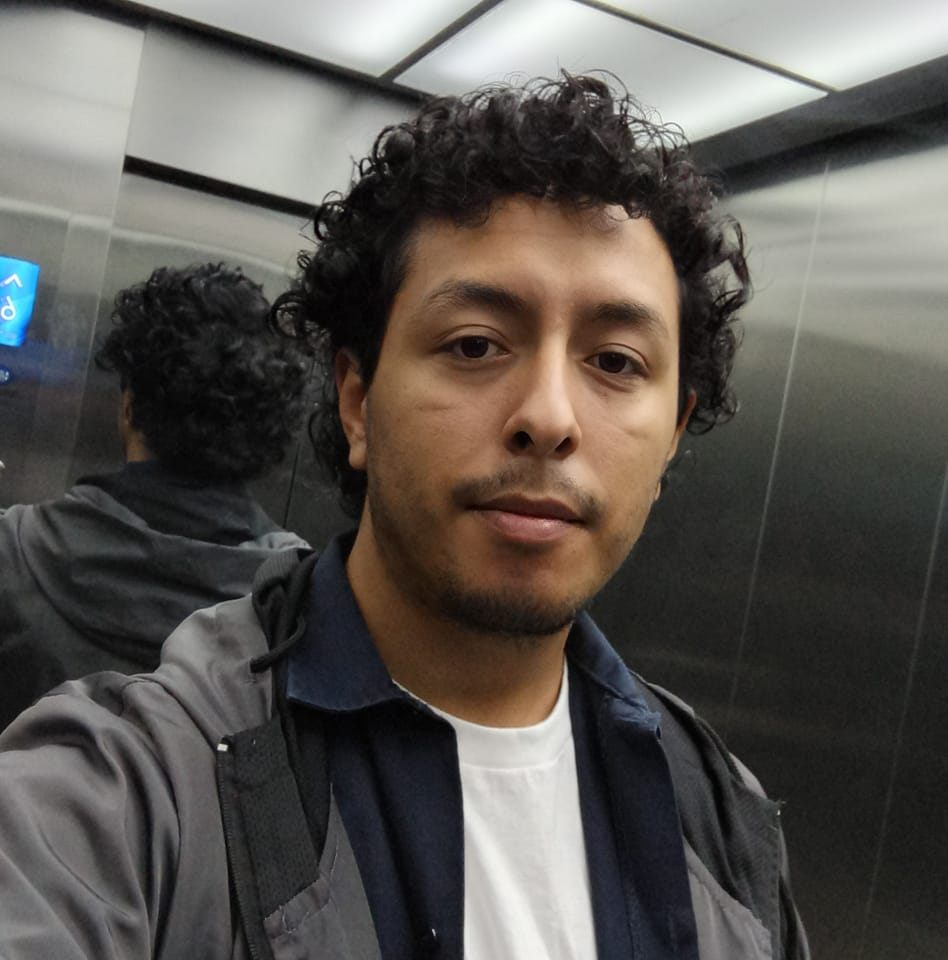

Student Name: **Cipriano Camacho Mario Tolentino**

Control Number: **20211961**

Institutional Email: **l20211961@tectijuana.edu.mx**

Degree Program: **Biomedical Engineering**

Course: **Digital Twins**

Instructor: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation Data

    time    x(t)      y(t)     z(t) 
    ____    _____    ______    _____

      0     0.517    19.939    0.281
      7      0.58    19.578    0.609
     14     0.726    18.678    1.063
     21     0.965    16.215    1.758
     28     1.282    14.005    2.752
     35     1.825    11.467    3.975
     42     2.473     8.096    4.895
     49     2.974     4.327    6.096
     56      3.43     1.287    7.152
     63     3.717     0.194    7.328
     70     3.829     0.056    7.232



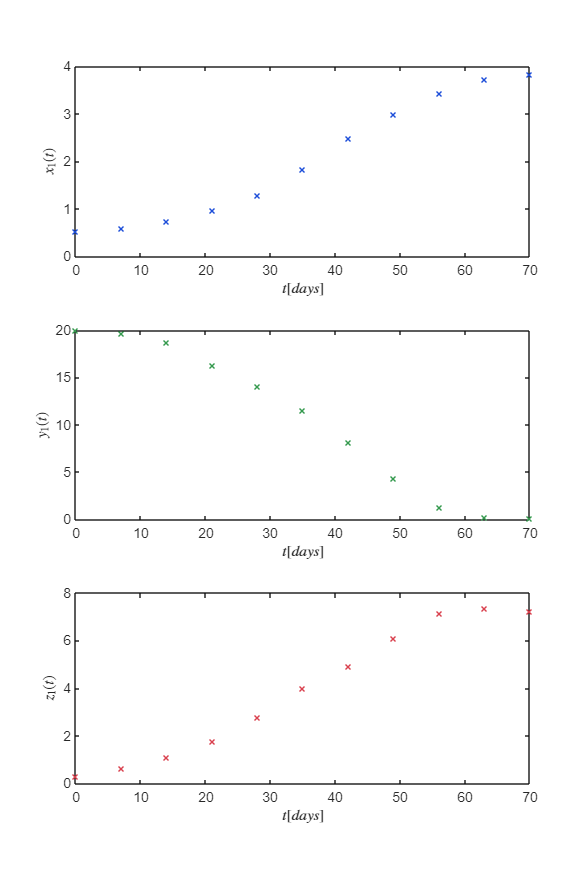

clc; clear; close all; warning('off','all')
filename = 'data.csv';
sys = readmatrix(filename);
to = sys(:,1); x1 = sys(:,5); y1 = sys(:,6); z1 = sys(: ,7);
T = array2table([to, x1,y1,z1], 'VariableNames', {'time', 'x(t)', 'y(t)', 'z(t)'});
disp(T); plotdata(to,x1,y1,z1,"n"); exportgraphics(gcf, 'Raw Data.pdf','ContentType','vector')

## Smooth Data

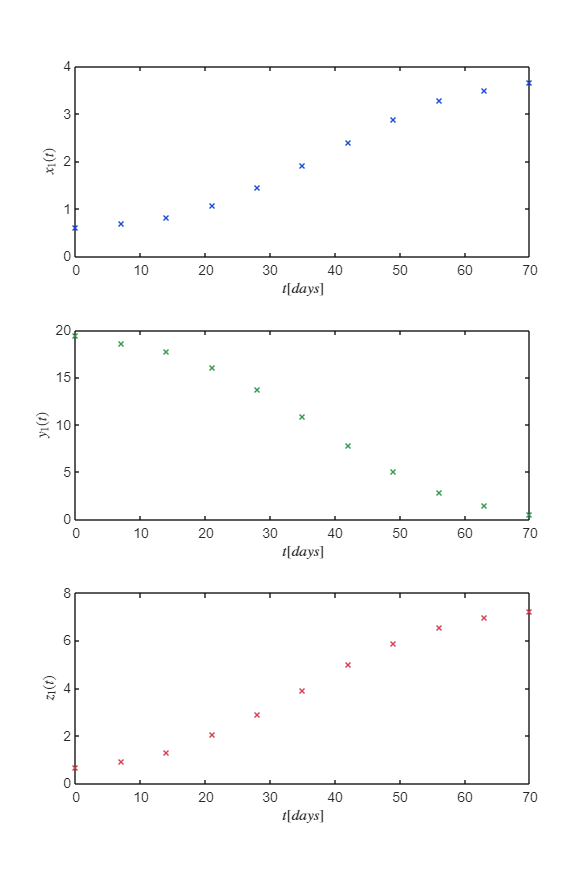

x1o = smoothdata(x1); y1o = smoothdata(y1); z1o = smoothdata(z1);
% T = table(to, x1o, y1o, z1o, 'VariableNames', {'time', 'X', 'Y', 'Z'});
writetable(T, 'data_smooth.csv'); plotdata(to,x1o,y1o,z1o,"n"); exportgraphics(gcf, 'Smooth Data.pdf','ContentType','vector')

## Nonlinear Algorithm

The equations from the nonlinear regression, obtained using the Eureqa software, are as follows:


$$\begin{array}{l}
\overset{\ldotp }{x} =p_1 \mathrm{xy}+p_2 xyz\\
\overset{\ldotp }{y} =p_3 y-p_4 xy;\\
\overset{\ldotp }{z} =p_5 z-p_6 xz;
\end{array}$$


P0 = [0.00116;
      0.00061;
      0.01394;
      0.02879;
      0.07415;
      0.01925];
[mdl,xa,ya,za] = variant(to,x1o,y1o,z1o,P0); 


Sample size (n): 11
Parameters to be estimated (pars): 6
Degrees of freedom: 27
Significance level (alpha): 0.05
t-Student values: 2.0518
Adjusted R-squared: 0.99979
Corrected AIC (n/pars < 40): -63.2947

    Parameters     Estimate         SE           MoE                 CI95                Pvalue  
    __________    __________    __________    __________    _______________________    __________

       p1         0.00049829    8.9285e-05     0.0001832    0.0003151    0.00068149    6.4259e-06
       p2         0.00078219    3.9423e-05    8.0888e-05    0.0007013    0.00086308    1.2468e-17
       p3           0.015288    0.00043368    0.00088984     0.014398      0.016178    4.0723e-24
       p4           0.031001    0.00059735     0.0012257     0.029775      0.032226    1.3818e-28
 

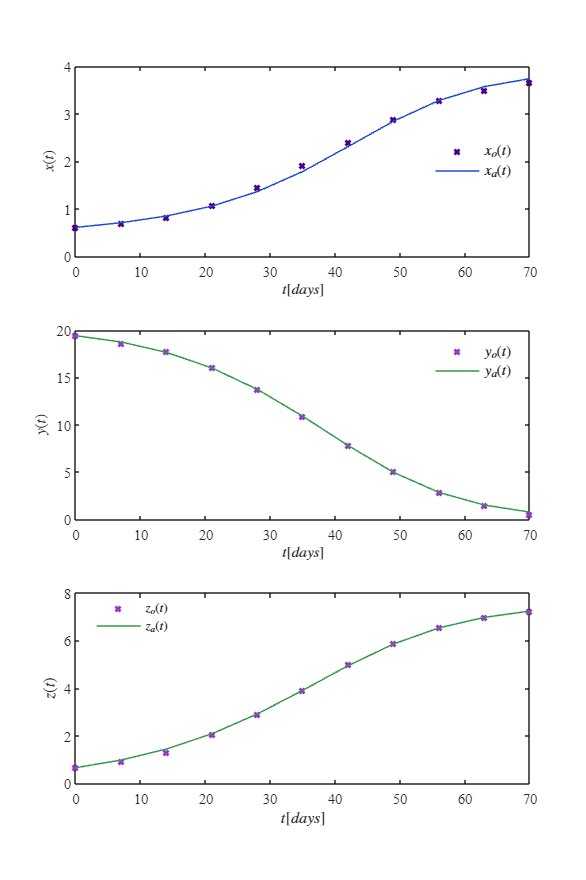

plotresults(to,[x1o,xa],[y1o,ya],[z1o,za],"n"); exportgraphics(gcf, 'Data Fitting.pdf','ContentType','vector')

## Equilibrium Points and Jacobian matrix

clear; close all; clc
syms x y z p1 p2 p3 p4 p5 p6

dx = p1*x*y + p2*x*y*z;
dy = p3*y - p4*x*y;
dz = p5*z - p6*x*z;

J = jacobian([dx,dy,dz],[x,y,z]);
fprintf('Jacobian matrix of the system: '); disp(J)

Jacobian matrix of the Lotka-Volterra system: 

$$\left(\begin{array}{ccc} p_{1}\,y+p_{2}\,y\,z & p_{1}\,x+p_{2}\,x\,z & p_{2}\,x\,y\\ -p_{4}\,y & p_{3}-p_{4}\,x & 0\\ -p_{6}\,z & 0 & p_{5}-p_{6}\,x \end{array}\right)$$

dx = p1*x*y + p2*x*y*z == 0;
dy = p3*y - p4*x*y == 0;
dz = p5*z - p6*x*z == 0;

edos = solve([dx,dy,dz],[x,y,z]);
fprintf(['The system has ', num2str(length(edos.x)), ' equilibrium points.'])

the Lotka-Volterra system has 2 equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1); Z0 = edos.z(1);
X1 = edos.x(2); Y1 = edos.y(2); Z1 = edos.z(2);

syms x0 y0 z0 x1 y1 z1
fprintf('Equilibrium points of the system: '); 

Equilibrium points of the Lotka-Volterra system: 

disp([x0,y0,z0,X0,Y0,Z0]); disp([x1,y1,z1,X1,Y1,Z1]); 

$$\left(\begin{array}{cccccc} x_{0} & y_{0} & z_{0} & \frac{p_{5}}{p_{6}} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccccc} x_{1} & y_{1} & z_{1} & 0 & 0 & 0 \end{array}\right)$$

clear p1 p2 p3 p4 p5 p6
p1 = 0.00049829; p2 = 0.00078219; p3 = 0.015288; 
p4 = 0.031001; p5 = 0.069085; p6 = 0.01741;

disp(['(x0,y0,z0) = (',num2str(p5/p6), ',0,0)']); disp('(x1,y1,z1) = (0,0,0)');  

(x0,y0,z0) = (3.9681,0,0)
(x1,y1,z1) = (0,0,0)


## Local Stability

clear; close all; clc;
p1 = 0.00049829; p2 = 0.00078219; p3 = 0.015288; 
p4 = 0.031001; p5 = 0.069085; p6 = 0.01741;

syms x y z
dx = p1*x*y + p2*x*y*z == 0;
dy = p3*y - p4*x*y == 0;
dz = p5*z - p6*x*z == 0;

edos = solve([dx,dy,dz],[x,y,z]);
X0 = double(edos.x(1)); Y0 = double(edos.y(1)); Z0 = double(edos.z(1));
X1 = double(edos.x(2)); Y1 = double(edos.y(2)); Z1 = double(edos.z(2));

clear x y z
x = [X0;X1]; y = [Y0;Y1]; z = [Z0;Z1];

var = {'(x0,y0,z0)';'(x1,y1,z1)'};
Equilibria = table(x,y,z,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye','ze'};
fprintf('Equilibrium points of the system: \n'); disp(Equilibria)

Equilibrium points of the Lotka-Volterra system: 
                    xe      ye    ze
                  ______    __    __

    (x0,y0,z0)    3.9681    0     0 
    (x1,y1,z1)         0    0     0 



for i = 1: length(x)
    J = [p1*y(i) + p2*y(i)*z(i),     p1*x(i) + p2*x(i)*z(i),     p2*x(i)*y(i);
         -p4*y(i),                   p3 - p4*x(i),               0;
         -p6*z(i),                   0,                          p5 - p6*x(i)];

    L(i,:) = eig(J);
end

L1 = L(:,1); L2 = L(:,2); L3 = L(:,3);
Lambdas = table(L1,L2,L3,'RowNames',var);
disp('Eigen vales of the Jacobian matrix evaluatedes at each equilibrium point:' ); disp(Lambdas)

Eigen vales of the Jacobian matrix evaluatedes at each equilibrium point:
                  L1       L2           L3    
                  __    ________    __________

    (x0,y0,z0)    0     -0.10773    1.3878e-17
    (x1,y1,z1)    0     0.015288      0.069085



## Algorithm in 2t

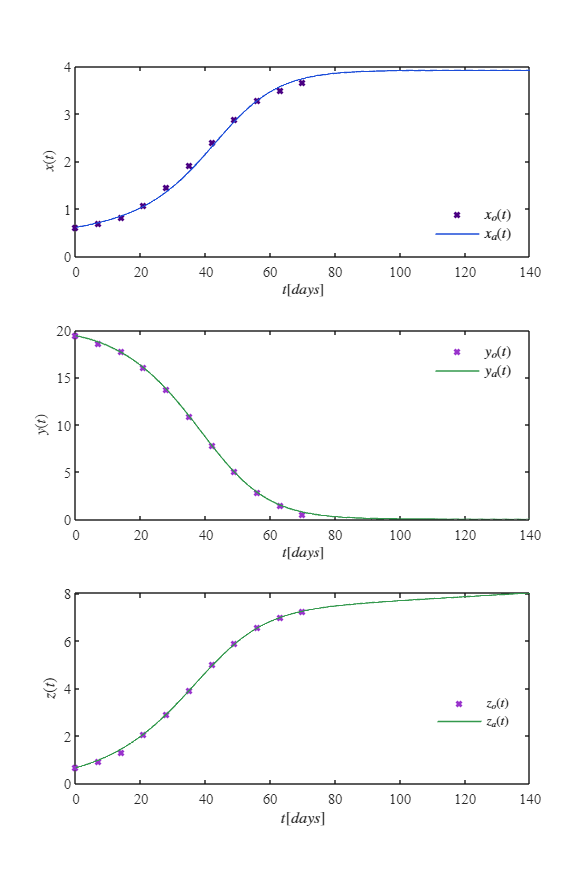

clc; clear; close all;
sys = readmatrix('data_smooth.csv');
to = sys(:,1);
x1o = sys(:,2);
y1o = sys(:,3);
z1o = sys(: ,4);
T2 = array2table([to,x1o,y1o,z1o], 'VariableNames', {'Tiempo', 'xo(t)', 'yo(t)', 'zo(t)'});
%disp(T2);
p1 = 0.00049829; p2 = 0.00078219; p3 = 0.015288; 
p4 = 0.031001; p5 = 0.069085; p6 = 0.01741;
P0 = [p1;p2;p3;p4;p5;p6];
[t_ext, xa, ya, za] = predict(to, x1o, y1o, z1o, P0);

plotext(t_ext,to,x1o,xa,y1o,ya,z1o,za,"n"); exportgraphics(gcf, '2t Prediction.pdf','ContentType','vector')

## **Model Explanation**


$$\begin{array}{l}
\overset{\ldotp }{x} =p_1 \mathrm{xy}+p_2 xyz\\
\overset{\ldotp }{y} =p_3 y-p_4 xy;\\
\overset{\ldotp }{z} =p_5 z-p_6 xz;
\end{array}$$


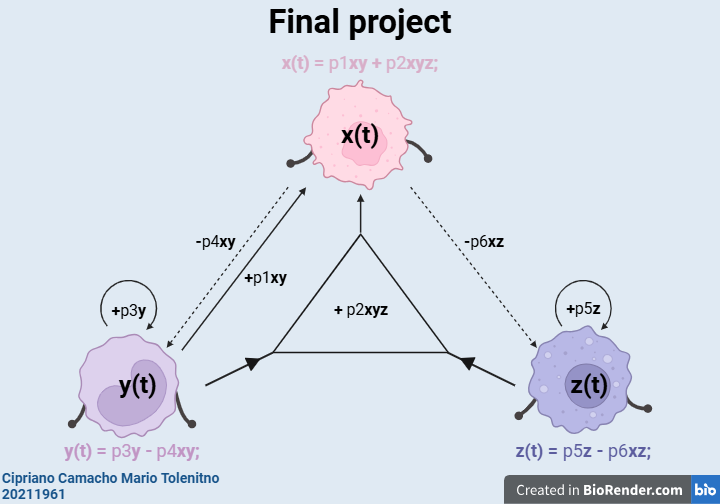

**Figure 1. Graphical representation of the model.**

This model describes the dynamics of three time-dependent variables: $x$, $y$, and $z$, and how they change based on themselves and each other, influenced by parameters $p_1$� through $p_6$�.

- **Equation for **$\mathrm{dx}$**:**

- The change in $x$ depends positively on the interaction between $x$ and $y$, scaled by $p_1$��.

- Additionally, $x$ also increases with the joint interaction of $x$, $y$, and $z$, scaled by $p_2$��.

- In other words, $x$ is driven by the presence of $y$, and even more so when $z$ is also present, suggesting that the combination of all three variables promotes the increase of $x$.

- **Equation for **$\mathrm{dy}$**:**

- The change in $y$ includes a positive linear term in $y$ itself, multiplied by $p_3$��, indicating a natural growth or reproduction of $y$.

- However, there is also a negative term proportional to the interaction between $x$ and $y$, scaled by $p_4$��, representing a decrease of $y$ when $x$ is present.

- This suggests that $x$ has an inhibitory or consuming effect on $y$, reducing its natural growth.

- **Equation for **$\mathrm{dz}$**:**

- Similarly to $y$, $z$ has a positive term proportional to its current value, scaled by $p_5$��, representing natural growth or reproduction.

- At the same time, there is a negative interaction term between $x$ and $z$, multiplied by $p_6$��, which reduces $z$ when $x$ is present.

- This indicates that $x$ also negatively affects $z$, inhibiting or consuming it.

**General summary:**

- $x$ is favored by the combined presence of $y$ and $z$, and grows through their interaction.

- $y$ and $z$ have their own growth but are inhibited or consumed by $x$.

- The model reflects a system where $x$ depends on the support or stimulation of $y$ and $z$, but at the same time $x$ limits the growth of these two variables.

## Functions

### Model functions

#### Nonlinear regression algorithm

function [mdl,xa,ya,za] = variant(to,xo,yo,zo,P0)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    to = [to;to;to];
    fo = [xo;yo;zo];

    function fi = model(P0,t)
        p1= P0(1); p2= P0(2); p3= P0(3); p4 = P0(4); p5 = P0(5); p6 = P0(6);

        dt = 1E-1;
        t = reshape(t,[],3); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        z = zeros(length(time),1); z(1) = z0;
        
        for i = 1:n
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn,fyn,fzn] = f(xn,yn,zn);
    
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end
    
        function [dx,dy,dz] = f(x,y,z)

        dx = p1*x*y + p2*x*y*z;
        dy = p3*y - p4*x*y;
        dz = p5*z - p6*x*z;

        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        zi = zeros(length(t),1);
        
        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
            zi(j) = z(k);
        end
        fi = [xi;yi;zi];
    end

    mdl = fitnlm(to,fo,@model,P0);
    fa = mdl.Fitted;
    fx = reshape(fa,[],3);
    xa = fx(:,1); ya = fx(:,2); za = fx(:,3);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['p1  ';'p2  ';'p3  ';'p4  ';'p5  ';'p6  '];
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    
    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student values: ', num2str(tval)])
    fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])

    disp(Results)
end

#### 2t Prediction

function [t_ext, xa, ya, za] = predict(to, xo, yo, zo, P0)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    to_concat = [to; to; to];
    fo = [xo; yo; zo];
    N = 2;

    function fi = model(P, t)
        p1 = P(1); p2 = P(2); p3 = P(3);
        p4 = P(4); p5 = P(5); p6 = P(6);

        dt = 1E-1;
        t_input = reshape(t, [], 3); 
        t_input = t_input(:,1);
        tmax = N * max(t_input);
        time = (0:dt:tmax)';

        n = length(time);
        x = zeros(n,1); x(1) = x0;
        y = zeros(n,1); y(1) = y0;
        z = zeros(n,1); z(1) = z0;

        for i = 1:n-1
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn,fyn,fzn] = f(xn,yn,zn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        function [dx,dy,dz] = f(x,y,z)
            dx = p1*x*y + p2*x*y*z;
            dy = p3*y - p4*x*y;
            dz = p5*z - p6*x*z;
        end

        xi = zeros(length(t_input),1);
        yi = zeros(length(t_input),1);
        zi = zeros(length(t_input),1);

        for j = 1:length(t_input)
            k = abs(time - t_input(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
            zi(j) = z(k);
        end
        fi = [xi; yi; zi];
    end

    t2 = fitnlm(to_concat, fo, @model, P0);
    P_fit = t2.Coefficients.Estimate;

    dt = 1E-1;
    tmax_ext = N * max(to);
    t_ext = (0:dt:tmax_ext)';

    function [x, y, z] = simulate(P, t)
        p1 = P(1); p2 = P(2); p3 = P(3);
        p4 = P(4); p5 = P(5); p6 = P(6);

        x = zeros(length(t),1); x(1) = x0;
        y = zeros(length(t),1); y(1) = y0;
        z = zeros(length(t),1); z(1) = z0;

        for i = 1:length(t)-1
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn,fyn,fzn] = f(xn,yn,zn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        function [dx,dy,dz] = f(x,y,z)
            dx = p1*x*y + p2*x*y*z;
            dy = p3*y - p4*x*y;
            dz = p5*z - p6*x*z;
        end
    end

    [xa, ya, za] = simulate(P_fit, t_ext);
end

### Plot Functions

#### Plot Data

function plotdata(t,x,y,z,norm)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,30])
    
    if norm == "s"
        x = (x - min(x)) / (max(x) - min(x));
        y = (y - min(y)) / (max(y) - min(y));
        z = (z - min(z)) / (max(z) - min(z));
    end

    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    title('Experimental data')

    subplot(3,1,1)
    plot(t,x,'x','MarkerSize',5,'LineWidth',1,'Color',c1)
    xlabel('$t [days]$','Interpreter','latex')
    ylabel('$x_1(t)$','Interpreter','latex')
    % xlim([0 max(t)+5]); xticks(0:max(t)/10:max(t)+5)
    % ylim([0 max(x)*1.1]); yticks(0:2:max(x)*1.1)

    % L = legend('$x_1(t)$');
    % set(L,'Interpreter','latex','Location','Best','Box','off');

    subplot(3,1,2)
    plot(t,y,'x','MarkerSize',5,'LineWidth',1,'Color',c2)
    xlabel('$t [days]$','Interpreter','latex')
    ylabel('$y_1(t)$','Interpreter','latex')
    % xlim([0 max(t)+5]); xticks(0:max(t)/10:max(t)+5)
    % ylim([0 max(y)*1.1]); yticks(0:2:max(y)*1.1)

    % L = legend('$y_1(t)$');
    % set(L,'Interpreter','latex','Location','Best','Box','off');

    subplot(3,1,3)
    plot(t,z,'x','MarkerSize',5,'LineWidth',1,'Color',c3)
    xlabel('$t [days]$','Interpreter','latex')
    ylabel('$z_1(t)$','Interpreter','latex')
    % xlim([0 max(t)+5]); xticks(0:max(t)/10:max(t)+5)
    % ylim([0 max(z)*1.1]); yticks(0:2:max(z)*1.1)

    % L = legend('$z_1(t)$');
    % set(L,'Interpreter','latex','Location','Best','Box','off');
end

#### Plot fitted and raw data

function plotresults(t,x,y,z,norm)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,30])
    
    if norm == "s"
        for i = 1:2
            x(:,i) = (x(:,i) - min(x(:,i))) / (max(x(:,i)) - min(x(:,i)));
            y(:,i) = (y(:,i) - min(y(:,i))) / (max(y(:,i)) - min(y(:,i)));
            z(:,i) = (z(:,i) - min(z(:,i))) / (max(z(:,i)) - min(z(:,i)));
        end
    end
    
    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    subplot(3,1,1)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',2,'Color',m1)
    plot(t,x(:,2),'-','LineWidth',1,'Color',c1)
    xlabel('$t [days]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')

    subplot(3,1,2)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t [days]$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')

    subplot(3,1,3)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,z(:,1),'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(t,z(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t [days]$','Interpreter','latex')
    ylabel('$z(t)$','Interpreter','latex')
    L = legend('$z_o(t)$','$z_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')
end

#### 2t Plot

function plotext(t_ext,to,x1o,x,y1o,y,z1o,z,norm)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,30])
    
    if norm == "s"
        x1o = (x1o - min(x1o)) / (max(x1o) - min(x1o));
        x = (x - min(x)) / (max(x) - min(x));

        y1o = (y1o - min(y1o)) / (max(y1o) - min(y1o));
        y = (y - min(y)) / (max(y) - min(y));

        z1o = (z1o - min(z1o)) / (max(z1o) - min(z1o));
        z = (z - min(z)) / (max(z) - min(z));
    end
    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    subplot(3,1,1)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(to,x1o,'x','MarkerSize',5,'LineWidth',2,'Color',m1)
    plot(t_ext,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t [days]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')

    subplot(3,1,2)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(to,y1o,'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(t_ext,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t [days]$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')

    subplot(3,1,3)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(to,z1o,'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(t_ext,z,'-','LineWidth',1,'Color',c2)
    xlabel('$t [days]$','Interpreter','latex')
    ylabel('$z(t)$','Interpreter','latex')
    L = legend('$z_o(t)$','$z_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')
end